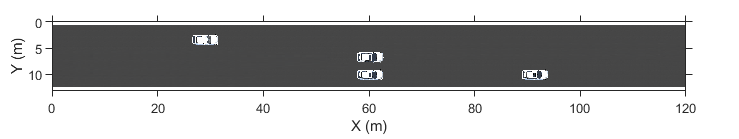

clear
sceneImage = imread ( '鸟瞰图处理后.png' );
imageSize = size(sceneImage);
xlims = [0 120]; % in 单位：米
ylims = [0 13];  % in 单位：米

sceneRef = imref2d(imageSize,xlims,ylims);

helperShowSceneImage(sceneImage, sceneRef) %显示图片

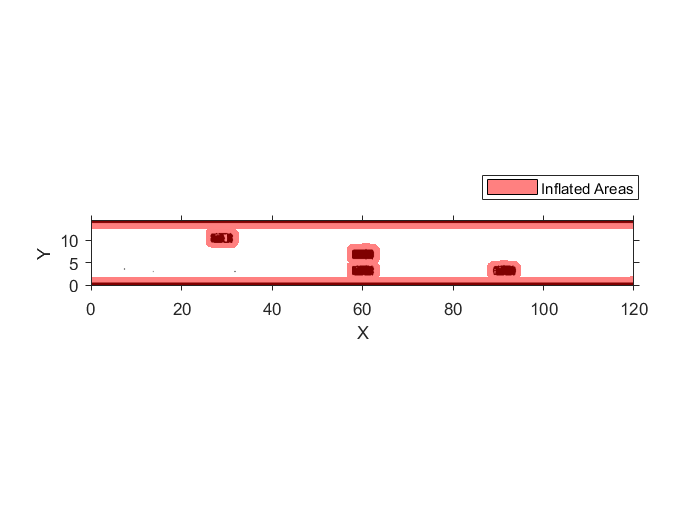

sceneImageBinary = helperCreateCostmapFromImage(sceneImage); %从RGB图片中生成costmap

% 获取地图左下角坐标
mapLocation = [sceneRef.XWorldLimits(1), sceneRef.YWorldLimits(1)]; % [meters, meters]

% 计算分辨率
mapWidth = sceneRef.XWorldLimits(2)-sceneRef.XWorldLimits(1); % meters
cellSize = mapWidth/size(sceneImageBinary, 2);

% 创建costmap
costmap = vehicleCostmap(im2single(sceneImageBinary), 'CellSize', cellSize, 'MapLocation', mapLocation);

figure
vehicleDims = vehicleDimensions;

% 3圆碰撞检查机制
numCircles = 3;
ccConfig = inflationCollisionChecker(vehicleDims,numCircles);
costmap.CollisionChecker = ccConfig;
plot(costmap)

legend('Position',[0.68871,0.61944,0.22393,0.047619])

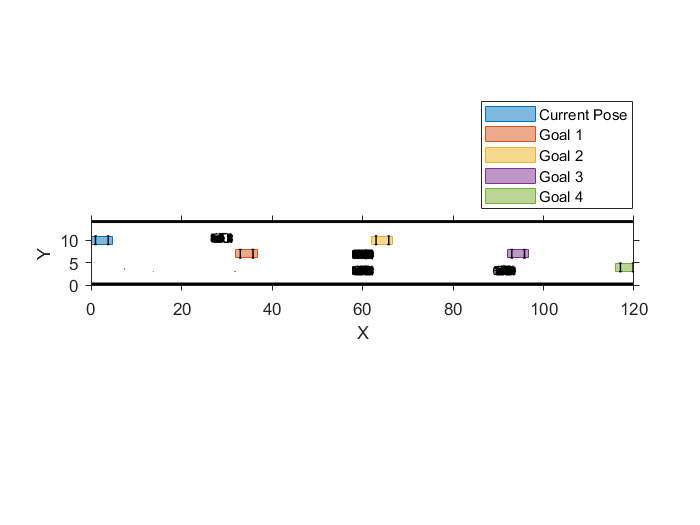

plot(costmap, 'Inflation', 'off')

maxSteeringAngle = 35;
currentPose = [1 10 0];

% 目标路径载入，并画出
data=load('routePlan.mat');
routePlan = data.routePlan;

hold on
helperPlotVehicle(currentPose, vehicleDims, 'DisplayName', 'Current Pose')
legend

for n = 1 : height(routePlan)
    vehiclePose = routePlan{n, 'EndPose'};
    legendEntry = sprintf('Goal %i', n);
    helperPlotVehicle(vehiclePose, vehicleDims, 'DisplayName', legendEntry);
end
hold off

legend('Position',[0.68663,0.60255,0.21821,0.20476])

% 利用HelperBehavioralPlanner类，创建行为规划器对象。 其requestManeuver方法从行为规划器请求导航任务流，直到到达目的地。
behavioralPlanner = HelperBehavioralPlanner(routePlan, maxSteeringAngle);

以下代码仅进行从起点到第一目标点的运动规划，利用该过程进行纵向速度PID控制器的参数调整。

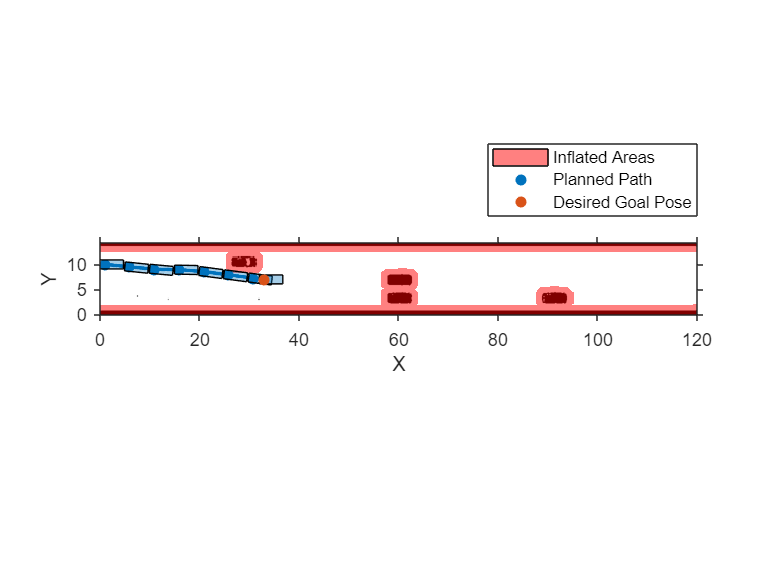

% 利用RRT*进行第一段路径规划
motionPlanner = pathPlannerRRT(costmap, 'MinIterations', 1000);

goalPose = routePlan{1, 'EndPose'};
refPath = plan(motionPlanner, currentPose, goalPose);

[transitionPoses, directions] = interpolate(refPath);

plot(motionPlanner)

legend('Position',[0.63472,0.62939,0.27143,0.11905])

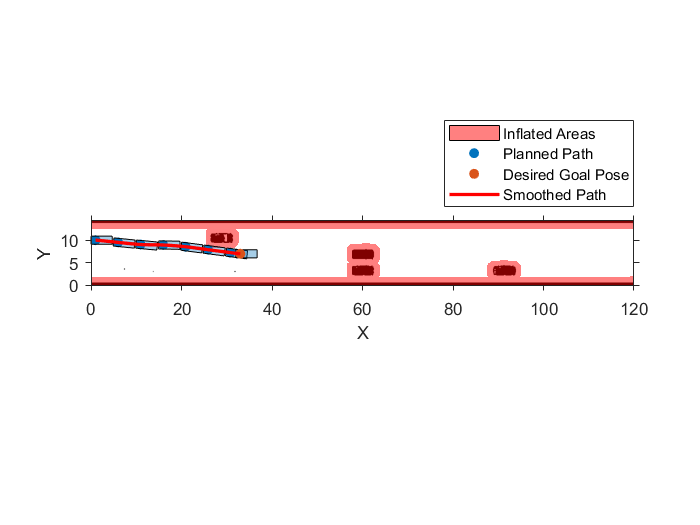

% 三次样条拟合平滑曲线，每一段长度为0.1m
approxSeparation = 0.1; % meters
numSmoothPoses   = round(refPath.Length / approxSeparation);

[refPoses, directions, cumLengths, curvatures] = smoothPathSpline(transitionPoses, directions, numSmoothPoses);

hold on
hSmoothPath = plot(refPoses(:, 1), refPoses(:, 2), 'r', 'LineWidth', 2, ...
    'DisplayName', 'Smoothed Path');
hold off

% 生成轨迹所匹配的参考速度,以2.5m/s^2的最大纵向加速度加速至3m/s后保持匀纵向加速度超车
% 此处重写helperGenerateVelocityProfile。以适应匀纵向速度超车条件，否则生成的速度分布图，每到一目标点速度均降为0
endSpeed   = 0; 
refVelocities=(GenerateVelocityProfile(0,3,cumLengths))';
% maxSpeed   = 5; % in meters/second
% startSpeed = 0; % in meters/second
% endSpeed   = 0; % in meters/second
% refVelocities = helperGenerateVelocityProfile(directions, cumLengths, curvatures, startSpeed, endSpeed, maxSpeed);

closeFigures;

vehicleSim = HelperVehicleSimulator(costmap, vehicleDims);
 
vehicleSim.setVehiclePose(currentPose);
currentVel = 0;
vehicleSim.setVehicleVelocity(currentVel);

vehicleSim.showTrajectory(true);

hideFigure(vehicleSim);

pathAnalyzer = HelperPathAnalyzer(refPoses, refVelocities, directions, ...
    'Wheelbase', vehicleDims.Wheelbase);
sampleTime = 0.05;
%lonController = HelperLongitudinalController('SampleTime', sampleTime);

controlRate = HelperFixedRate(1/sampleTime);

reachGoal = false;

% 此处用于PID控制
i=0;
myTime(1)=0;
Error=0;
ErrorIntegral=0;

while ~reachGoal    
    
    [refPose, refVel, direction] = pathAnalyzer(currentPose, currentVel);
    
    
    updateDrivingDirection(vehicleSim, direction);
    
    % Stanley函数计算方向盘转角
    steeringAngle = lateralControllerStanley(refPose, currentPose, currentVel, ...
        'Direction', direction, 'Wheelbase', vehicleDims.Wheelbase);
    
    % 重写，纵向速度PID控制器，加入微分项
%     lonController.Direction = direction;
%     [accelCmd, decelCmd] = lonController(refVel, currentVel);
    
    [accelCmd, decelCmd,Error] =PIDController(refVel, currentVel,Error,ErrorIntegral,sampleTime);
    ErrorIntegral=Error*sampleTime+ErrorIntegral;
    
    
    drive(vehicleSim, accelCmd, decelCmd, steeringAngle);
    
    % 修改helperGoalChecker的检测条件，将到达目标的检测条件由速度为0改为当前点距目标点的欧拉距离小于0.1
    % 此修改为了适应匀纵向速度超车假设，到达中间目标点时速度不降为0
    reachGoal = helperGoalChecker(goalPose, currentPose, currentVel, endSpeed,direction);
    
    
    waitfor(controlRate);
    
    % 此处代码用于记录采样时间下的预期速度，实际速度，预期位置，实际位置
    % 用于修改PID参数时观测控制器时域指标
    % 不调整PID时可以删除
    i=i+1;
    if(i>1)
    myTime(i)=myTime(i-1)+0.05;
    end
    currentV(i)=currentVel;
    refV(i)=refVel;
    refPoseList(i,:)=refPose;
    poseList(i,:)=currentPose;
    %
    
    currentPose  = getVehiclePose(vehicleSim);
    currentVel   = getVehicleVelocity(vehicleSim);

end

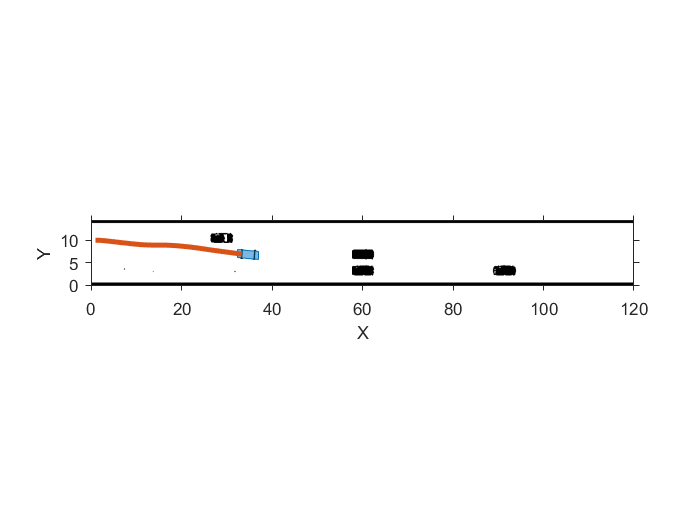


showFigure(vehicleSim);

以下代码实现全过程的运动规划

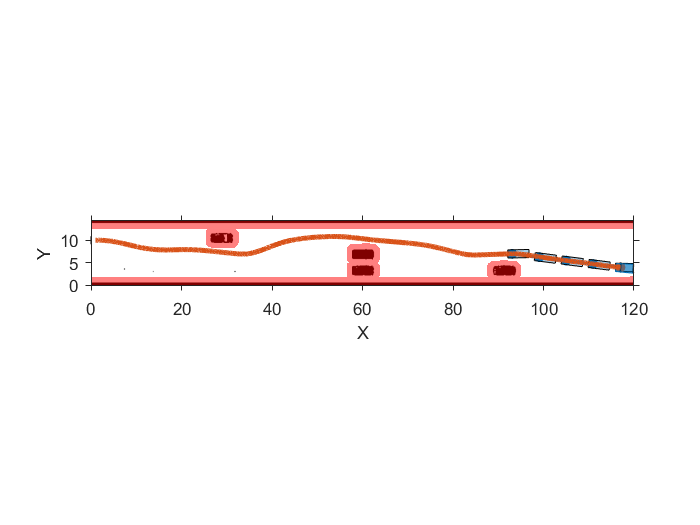

% 此处利用behavioralPlanner分4段实现超车
currentPose = [1 10 0]; 
vehicleSim.setVehiclePose(currentPose);

currentVel  = 0; 
vehicleSim.setVehicleVelocity(currentVel);
i=0;
myTime(1)=0;
Error=0;
ErrorIntegral=0;
while ~reachedDestination(behavioralPlanner)
    
    
    [nextGoal, plannerConfig, speedConfig] = requestManeuver(behavioralPlanner, ...
        currentPose, currentVel);
    
    
    configurePlanner(motionPlanner, plannerConfig);
    
    
    refPath = plan(motionPlanner, currentPose, nextGoal);
    plot(motionPlanner);
    legend off

    isReplanNeeded = ~checkPathValidity(refPath, costmap);
    if isReplanNeeded
        warning('Unable to find a valid path. Attempting to re-plan.')
        
        replanNeeded(behavioralPlanner);
        continue;
    end
    
    [transitionPoses, directions] = interpolate(refPath);
     
    numSmoothPoses   = round(refPath.Length / approxSeparation);
    [refPoses, directions, cumLengths, curvatures] = smoothPathSpline(transitionPoses, directions, numSmoothPoses);
    
%     refVelocities = helperGenerateVelocityProfile(directions, cumLengths, curvatures, startSpeed, endSpeed, maxSpeed);
    refVelocities=(GenerateVelocityProfile(currentVel,3,cumLengths))';

    pathAnalyzer.RefPoses     = refPoses;
    pathAnalyzer.Directions   = directions;
    pathAnalyzer.VelocityProfile = refVelocities;
     
    %reset(lonController);
    
    reachGoal = false;
   


    while ~reachGoal  
        [refPose, refVel, direction] = pathAnalyzer(currentPose, currentVel);
        
        updateDrivingDirection(vehicleSim, direction);
        
        steeringAngle = lateralControllerStanley(refPose, currentPose, currentVel, ...
            'Direction', direction, 'Wheelbase', vehicleDims.Wheelbase);
        
%         lonController.Direction = direction;
%         [accelCmd, decelCmd] = lonController(refVel, currentVel);
        [accelCmd, decelCmd,Error] =PIDController(refVel, currentVel,Error,ErrorIntegral,sampleTime);
        ErrorIntegral=Error*sampleTime+ErrorIntegral;
        
    % 此处代码用于记录采样时间下的预期速度，实际速度，预期位置，实际位置
    % 用于修改PID参数时观测控制器时域指标
    % 不调整PID时可以删除        
    i=i+1;
    if(i>1)
    myTime(i)=myTime(i-1)+0.05;
    end
    currentV(i)=currentVel;
    refV(i)=refVel;
    refPoseList(i,:)=refPose;
    poseList(i,:)=currentPose;
    %
    
        drive(vehicleSim, accelCmd, decelCmd, steeringAngle);
        
        reachGoal = helperGoalChecker(nextGoal, currentPose, currentVel, speedConfig.EndSpeed, direction);
        
        waitfor(controlRate);
        
        currentPose  = getVehiclePose(vehicleSim);
        currentVel   = getVehicleVelocity(vehicleSim);
    end
end


showFigure(vehicleSim);

%%三维仿真
% 加载平滑处理后的坐标和位姿数据
load('myRefX.mat');
load('myRefY.mat');
load('myRefYaw.mat');

% 打开仿真
open_system('3Dsimulation');

% 运行仿真（需要安装Unreal Engine4.25）
sim('3Dsimulation');

%% Supporting Functions

function BW = helperCreateCostmapFromImage(sceneImage) 
%helperCreateCostmapFromImage Create a costmap from an RGB image.

% Call the autogenerated code from the Color Thresholder app
BW = helperCreateMask(sceneImage);

% Smooth the image
BW = im2uint8(medfilt2(BW));

% Resize
BW = imresize(BW, 0.5);

% Compute complement 
BW = imcomplement(BW);
end

%%%
% *helperCreateMask*
function [BW,maskedRGBImage] = helperCreateMask(RGB) 
%helperCreateMask  Threshold RGB image using auto-generated code from Color Thresholder app.
%  [BW,maskedRGBImage] = createMask(RGB) thresholds image RGB using
%  autogenerated code from the Color Thresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB image is returned in maskedRGBImage.

% Convert RGB image to chosen colorspace
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 67.000;
channel1Max = 216.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 68.000;
channel2Max = 171.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 69.000;
channel3Max = 160.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image
maskedRGBImage = I;

% When BW is false, set background pixels to zero
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
end

%%%
% *helperCloseFigures*
function helperCloseFigures()
%helperCloseFigures Close all the figures except the simulation visualization

% Find all the figure objects
figHandles = findobj('Type', 'figure');

% Close the figures
for i = 1: length(figHandles)
    close(figHandles(i));
end
end

%%%
% *PIDController*
function [accelCmd, decelCmd,Error] =PIDController(refVel, currentVel,lastError,ErrorIntegral,sampleTime)
% PID控制器重写
    Kp=28;
    Ki=1;
    Kd=0;

    MaxAcceleration=2.5;
    Error= refVel - currentVel;
    if Kp*Error+Ki*(ErrorIntegral+Error*sampleTime)+Kd*(Error-lastError)>0
        accelCmd=min(Kp*Error+Ki*(ErrorIntegral+Error*sampleTime)+Kd*(Error-lastError),MaxAcceleration);
        decelCmd = 0;
    else
        accelCmd=0;
        decelCmd=-(Kp*Error+Ki*(ErrorIntegral+Error*sampleTime)+Kd*(Error-lastError));
    end
    
       
end

function configurePlanner(pathPlanner, config)

fieldNames = fields(config);
for n = 1 : numel(fieldNames)
    if ~strcmpi(fieldNames{n}, 'IsParkManeuver')
        pathPlanner.(fieldNames{n}) = config.(fieldNames{n});
    end
end
end


function refVelocities=GenerateVelocityProfile(startSpeed,endSpeed,cumLengths)
% 重写，速度分布生成
    MaxLongitudinalAccel=2.5;
    accl=2.5;
    MaxLongitudinalDccel=5;
    refVelocities(1)=startSpeed;
    if startSpeed==0
        for i=2:size(cumLengths)
            if refVelocities(i-1)<(endSpeed-1)
                refVelocities(i)=sqrt((refVelocities(i-1))^2+2*MaxLongitudinalAccel*0.1);
            elseif refVelocities(i-1)<(endSpeed-0.02)
                refVelocities(i)=sqrt((refVelocities(i-1))^2+2*accl*0.1);
                accl=accl-0.1;
            else
                refVelocities(i)=endSpeed;
            end
        end
    elseif endSpeed==0
        for i=2:size(cumLengths)
            if refVelocities(i-1)>2.5
                refVelocities(i)=sqrt((refVelocities(i-1))^2-2*MaxLongitudinalDccel*0.1);
            else
                refVelocities(i)=1.5;
            end
        end 
        
    else
        for i=2:size(cumLengths)
            refVelocities(i)=startSpeed;
        end
    end
        
end
